## Implementazione della densità normale bivariata  tramite meshgrid

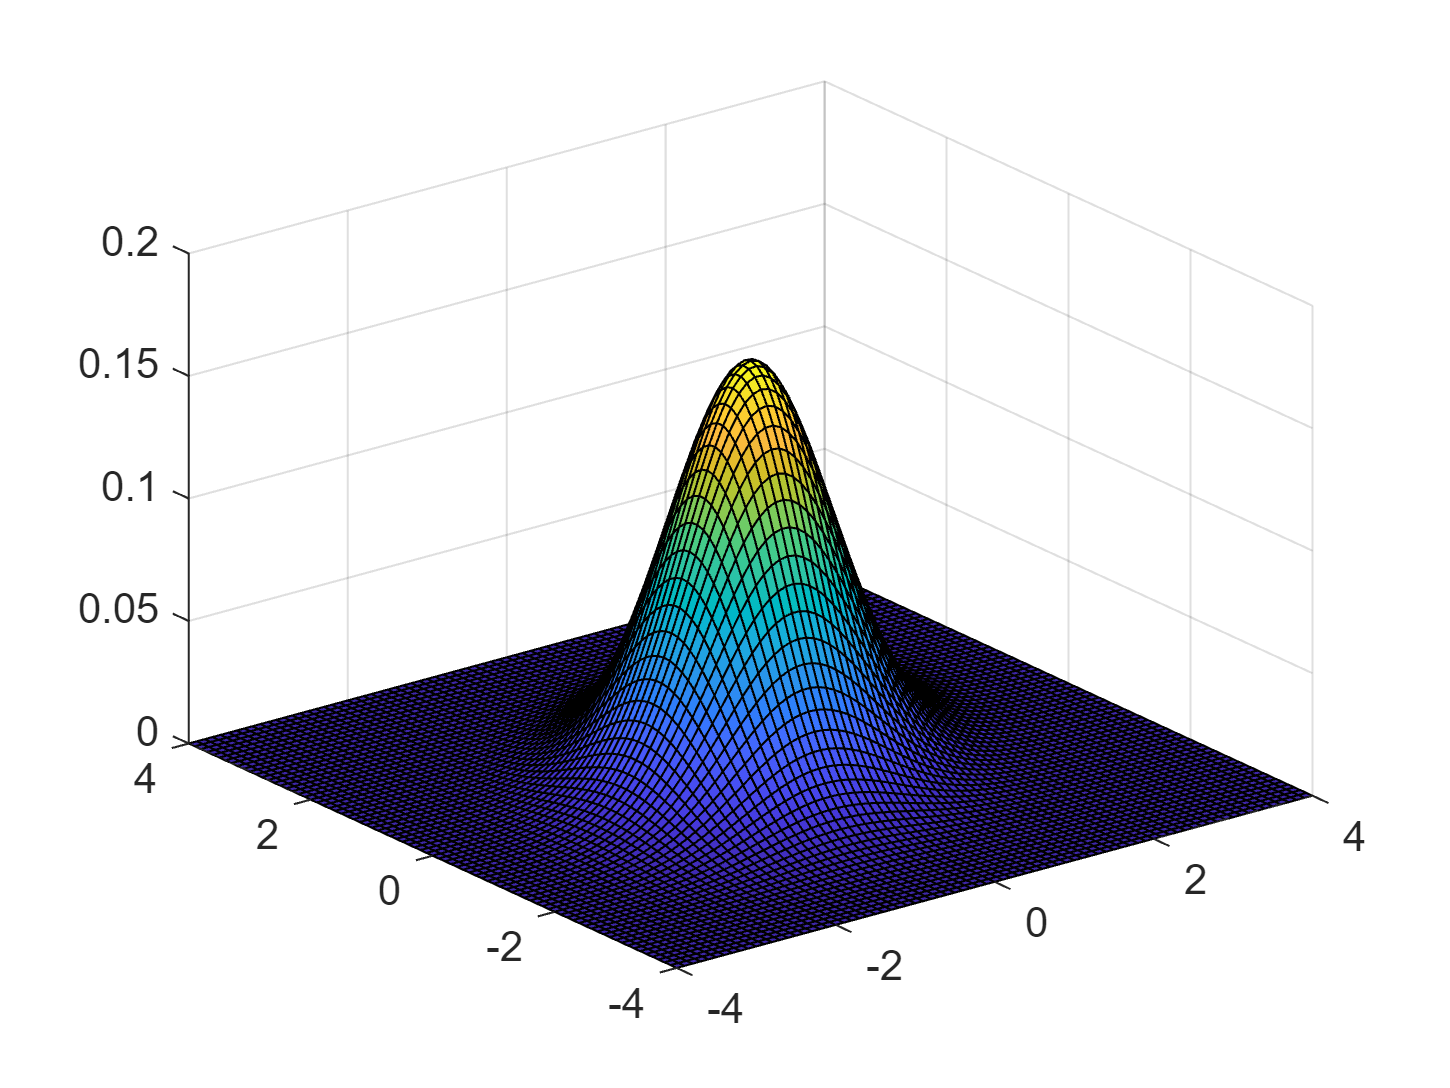

% Per inserire lo slider dal menu insert Control|Numeric Slider.
% Dx del mouse  sul controllo "Configure Control" per impostare min. max.
% passo (Step) e la label da inserire quando si fa click su Hide code
rho=0.3;
seqx=(-4:0.1:4);
[x,y]=meshgrid(seqx);
dens2=(1/(2*pi*sqrt(1-rho^2)))...
    *exp(-(1/(2*(1-rho^2)))*(x.^2+y.^2-2*rho*x.*y));
surf(x,y,dens2)

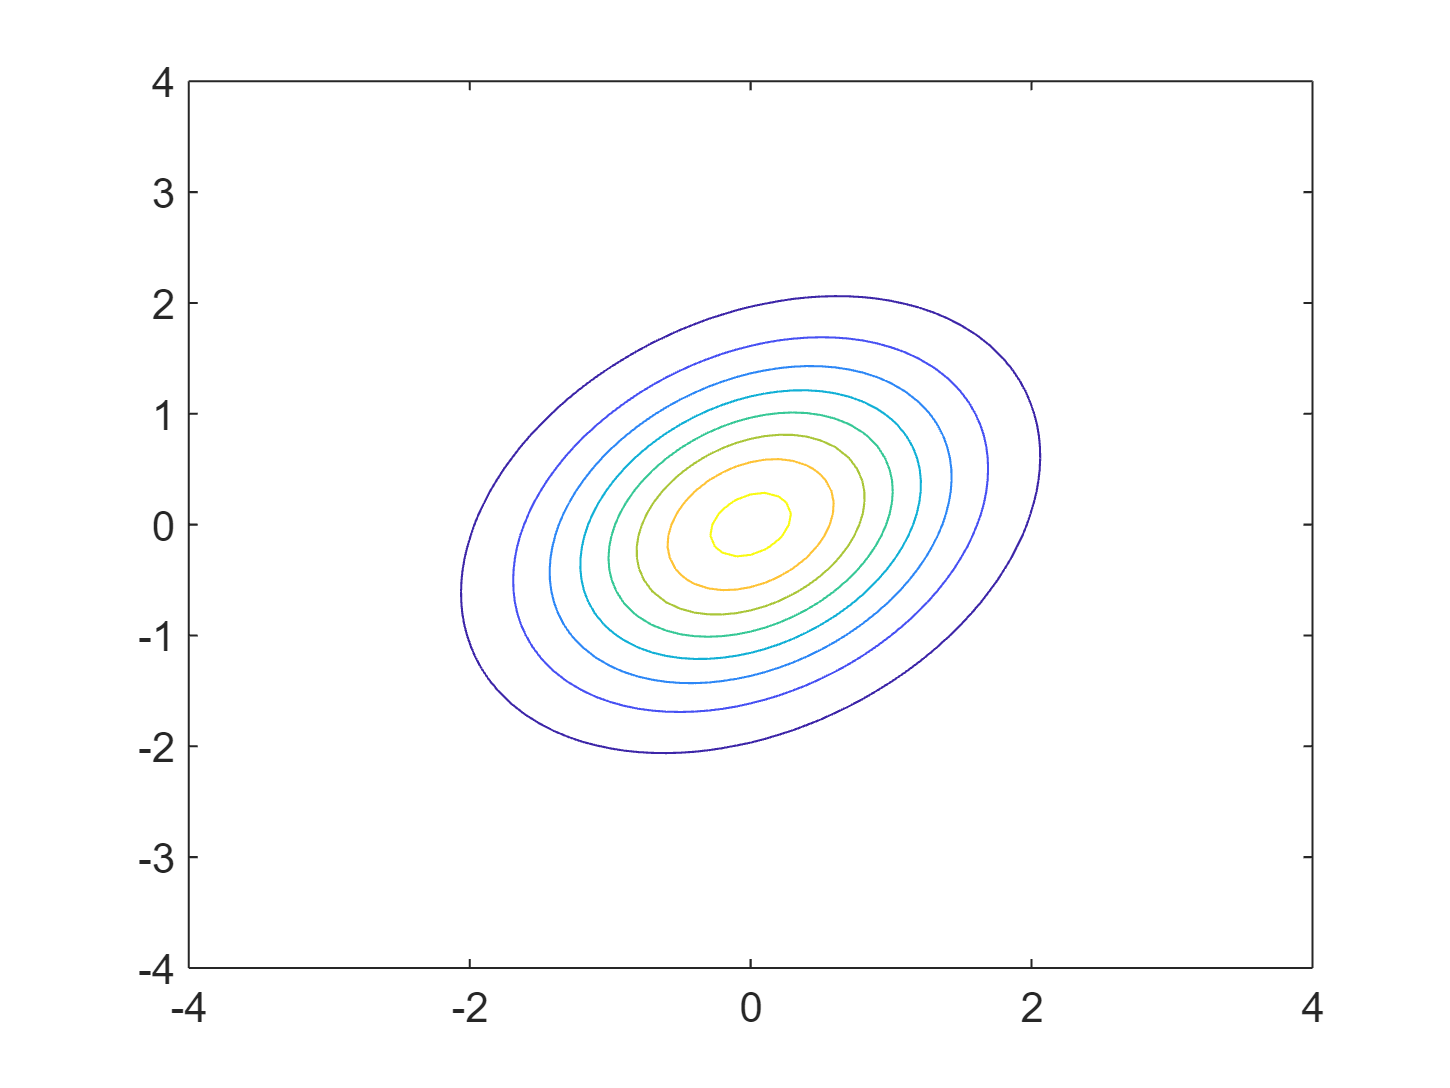

contour(x,y,dens2)

## Implementazione della densità normale bivariata senza cicli for e senza meshgrid

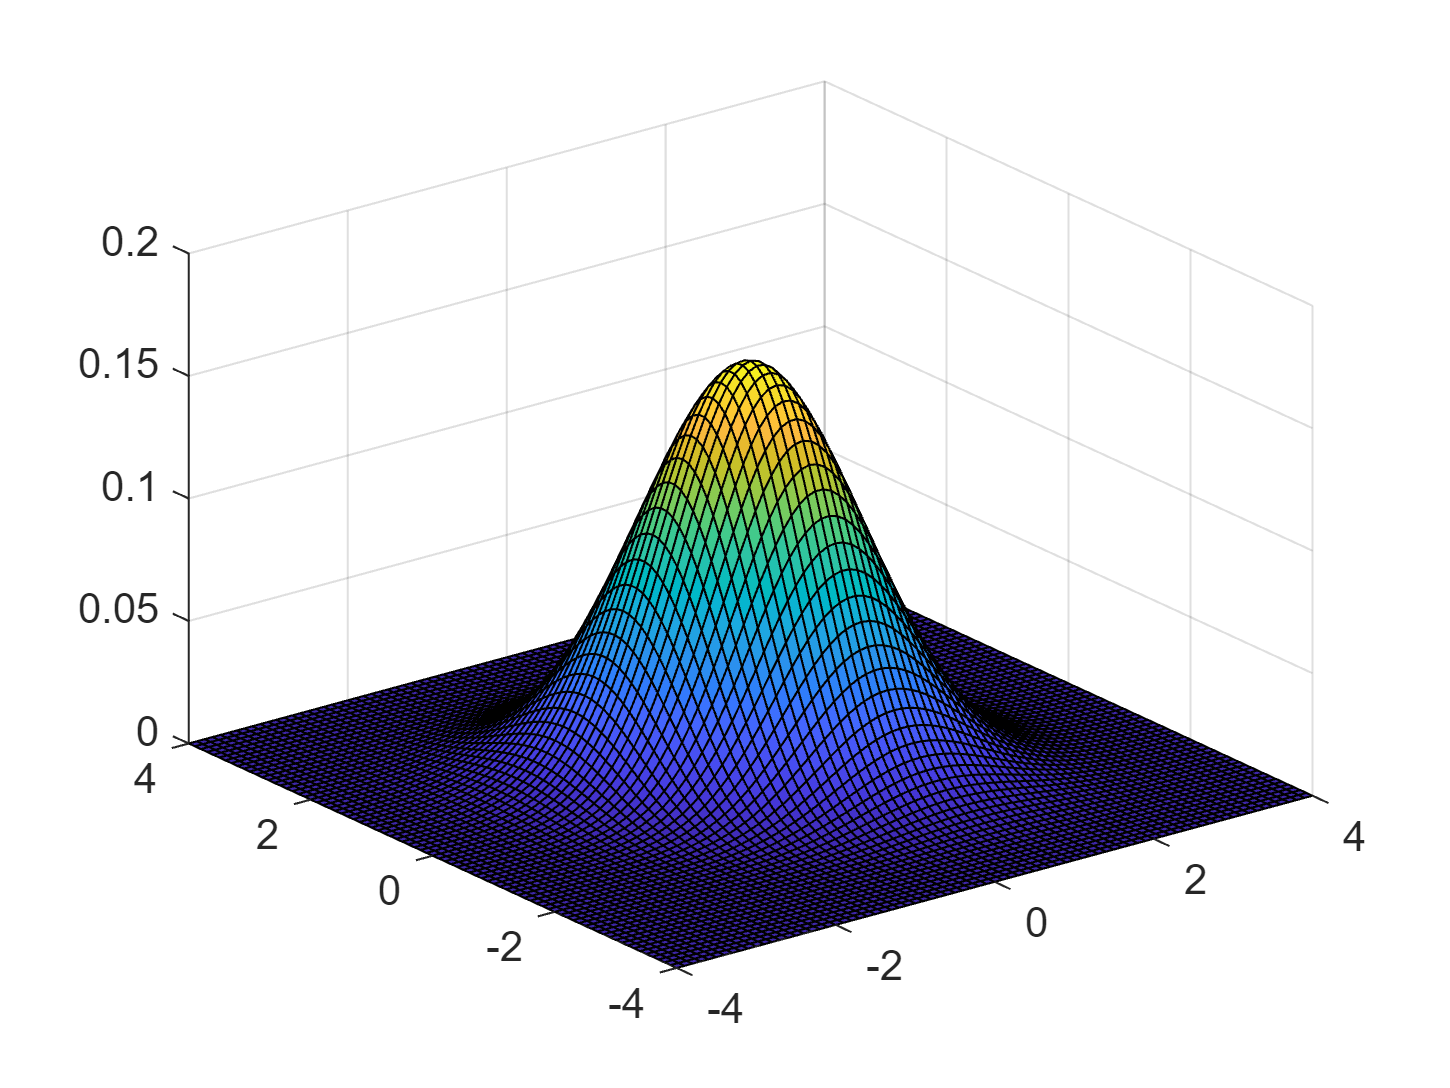

rho=-0.3;
seqx=(-4:0.1:4)'; % seqx definito come vettore colonna
seqy=seqx';  % seqy definito come vettore riga
% si noti che seqx * seqy è una matrice di dimensione length(seqx)-by-length(seqy) il cui generico elemento è
% seqx(i)*seqy(j)
% Similmente seqx+seqy è una matrice di dimensione length(seqx)-by-length(seqy) il cui generico elemento è
% seqx(i)+seqy(j)
dens1=(1/(2*pi*sqrt(1-rho^2)))...
    *exp(-(1/(2*(1-rho^2)))*(seqx.^2+seqy.^2-2*rho*seqx*seqy));
% La matrice dens1 è esattamente uguale alla matrice dens ottenuta
% nella sezione precedente
surf(seqx,seqy,dens1)

## Implementazione della densità normale bivariata tramite doppio ciclo for

% Creazione della sequenza da -4 a 4 con passo di 0.1
% Dato che le sequenze su x e su y sono le stesse basta creare un'unica
% sequenza
seq=-4:0.1:4;
lseq=length(seq);
% dens= inizializzazione della matrice dens il cui generico elemento (i,j)
% conterrà la densità della distribuzione normale bivariata in
% corrispondenza f(seq(i), seq(j)) con i=1,2, ..., lseq e j=1, 2, ..., lseq
dens=zeros(lseq,lseq);

% Per inserire lo slider dal menu insert|Control|NumericSlider.
% Dx del mouse  sul controllo per impostare min. max e passo
rho=-0.3;
for i=1:lseq
    for j=1:lseq
        dens(i,j)=(1/(2*pi*sqrt(1-rho^2)))...
            *exp(-(1/(2*(1-rho^2)))*(seq(i)^2+seq(j)^2-2*rho*seq(i)*seq(j)));
    end
end

surf(seq,seq,dens)